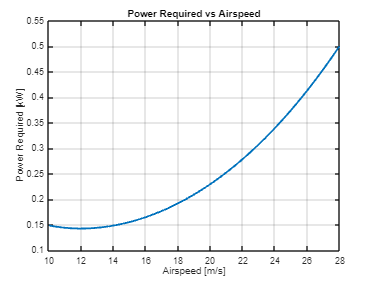

%% ========================================================================
% MISSION-LEVEL DIGITAL TWIN FOR UAV OPERATIONS
% COMPLETE THESIS-GRADE IMPLEMENTATION
%
% Author : Pranav Subramanian (M.Tech)
%
% PURPOSE:
% Physics-based mission feasibility, energy, time, and risk evaluation
% framework for UAV operations with full observability.
%
% REFERENCES:
% [1] Glaessgen & Stargel, NASA, 2012 (Digital Twin Paradigm)
% [2] Beard & McLain, Princeton, 2012 (UAV Modeling)
% [3] Raymer, AIAA, 2018 (Performance Estimation)
% [4] Langelaan, JGCD, 2007 (Energy-based Guidance)
% [5] Frazzoli et al., 2002 (Planning with Disturbances)
%% ========================================================================

clc; clear; close all;

%% ========================================================================
% 1. GLOBAL CONSTANTS
% ========================================================================

g = 9.81;                               % gravity [m/s^2]

%% ========================================================================
% 2. VEHICLE PARAMETERS
% ========================================================================

S   = 0.8;                              % wing area [m^2]
CD0 = 0.03;
k   = 0.045;
eta_prop = 0.7;

mass_empty   = 8;
mass_payload = 2;
m = mass_empty + mass_payload;
W = m * g;

%% ========================================================================
% 3. BATTERY MODEL
% ========================================================================

E_batt_max  = 1200 * 3600;              % [J]
SOC_init    = 1.0;
SOC_reserve = 0.25;

%% ========================================================================
% 4. ENVIRONMENT MODEL
% ========================================================================

h = 120;                               % altitude [m]
rho0 = 1.225;
H = 8500;
rho = rho0 * exp(-h/H);

wind_mean  = 4;
wind_sigma = 1.2;
wind_dir   = pi;

%% ========================================================================
% 5. VEHICLE PERFORMANCE MAP
% ========================================================================

V_range = linspace(10,28,40);
P_map = zeros(size(V_range));

for i = 1:length(V_range)
    V = V_range(i);
    CL = W / (0.5 * rho * V^2 * S);
    CD = CD0 + k * CL^2;
    D  = 0.5 * rho * V^2 * S * CD;
    P_map(i) = D * V / eta_prop;
end

%% ========================================================================
% 6. PLOT: POWER REQUIRED VS AIRSPEED
% ========================================================================

figure;
plot(V_range, P_map/1000,'LineWidth',2);
xlabel('Airspeed [m/s]');
ylabel('Power Required [kW]');
title('Power Required vs Airspeed');
grid on;

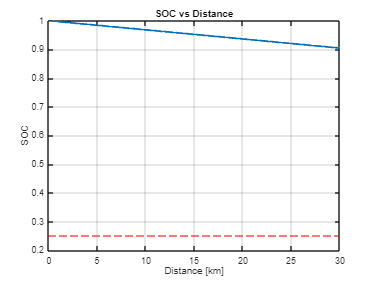


%% ========================================================================
% 7. SELECT CRUISE CONDITION
% ========================================================================

V_air = 18;
CL = W / (0.5 * rho * V_air^2 * S);
CD = CD0 + k * CL^2;
Drag = 0.5 * rho * V_air^2 * S * CD;
P_cruise = Drag * V_air / eta_prop;

%% ========================================================================
% 8. MISSION DEFINITIONS
% ========================================================================

routes(1).name = 'Route A';
routes(1).distance = 30000;

routes(2).name = 'Route B';
routes(2).distance = 38000;

routes(3).name = 'Route C';
routes(3).distance = 45000;

ds = 50;

loiter_time = 300;
V_loiter = 14;

ToT_required = 1900;

%% ========================================================================
% 9. NOMINAL WIND
% ========================================================================

Vw_nominal = wind_mean * cos(wind_dir);

%% ========================================================================
% 10. ROUTE SIMULATION
% ========================================================================

results = struct;

for r = 1:length(routes)

    [s, SOC, time, power_profile] = mission_model( ...
        routes(r).distance, V_air, V_loiter, loiter_time, ...
        P_cruise, rho, S, CD0, k, W, ds, Vw_nominal, ...
        E_batt_max, SOC_init);

    results(r).name = routes(r).name;
    results(r).s = s;
    results(r).SOC = SOC;
    results(r).time = time;
    results(r).power = power_profile;

    results(r).SOC_final = SOC(end);
    results(r).time_total = time(end);
    results(r).energy_margin = SOC(end) - SOC_reserve;
    results(r).energy_ok = results(r).energy_margin >= 0;
    results(r).ToT_ok = time(end) <= ToT_required;
end

%% ========================================================================
% 11. RETURN-TO-BASE CHECK
% ========================================================================

for r = 1:length(results)

    [~, SOC_rtb, ~, ~] = mission_model( ...
        routes(r).distance, V_air, V_loiter, 0, ...
        P_cruise, rho, S, CD0, k, W, ds, Vw_nominal, ...
        E_batt_max, results(r).SOC_final);

    results(r).RTB_ok = SOC_rtb(end) >= SOC_reserve;
end

%% ========================================================================
% 12. MONTE CARLO WIND RISK
% ========================================================================

N_mc = 300;
SOC_mc = zeros(N_mc,length(routes));

for r = 1:length(routes)
    for k_mc = 1:N_mc
        Vw = (wind_mean + wind_sigma*randn) * cos(wind_dir);
        [~, SOC_tmp, ~, ~] = mission_model( ...
            routes(r).distance, V_air, V_loiter, loiter_time, ...
            P_cruise, rho, S, CD0, k, W, ds, Vw, ...
            E_batt_max, SOC_init);
        SOC_mc(k_mc,r) = SOC_tmp(end);
    end
    results(r).P_success = mean(SOC_mc(:,r) >= SOC_reserve);
    results(r).risk = 1 - results(r).P_success;
end

%% ========================================================================
% ========================== PLOTS SECTION ================================
% ========================================================================

% PLOT 1: SOC vs Distance
figure;
plot(results(1).s/1000, results(1).SOC,'LineWidth',2);
yline(SOC_reserve,'r--');
xlabel('Distance [km]'); ylabel('SOC');
title('SOC vs Distance');
grid on;

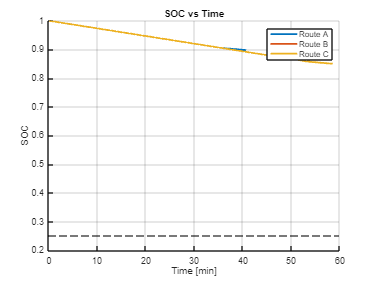


% PLOT 2: SOC vs Time (all routes)
figure; hold on;
for r = 1:length(results)
    plot(results(r).time/60, results(r).SOC,'LineWidth',2);
end
yline(SOC_reserve,'k--');
xlabel('Time [min]'); ylabel('SOC');
title('SOC vs Time');
legend(results.name); grid on;

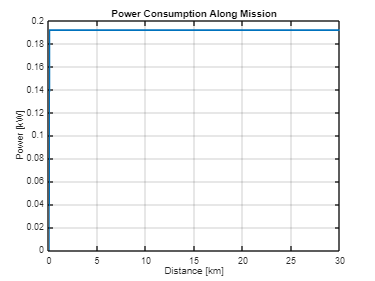


% PLOT 3: Power vs Distance
figure;
plot(results(1).s/1000, results(1).power/1000,'LineWidth',2);
xlabel('Distance [km]');
ylabel('Power [kW]');
title('Power Consumption Along Mission');
grid on;

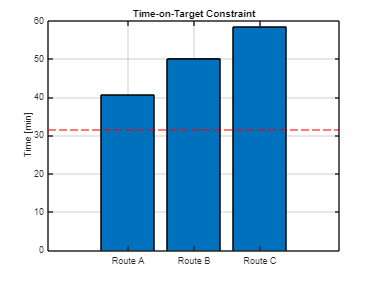


% PLOT 4: Time-on-Target
figure;
bar([results.time_total]/60);
yline(ToT_required/60,'r--');
set(gca,'XTickLabel',{results.name});
ylabel('Time [min]');
title('Time-on-Target Constraint');
grid on;

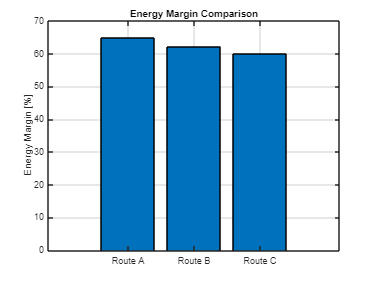


% PLOT 5: Energy Margin
figure;
bar([results.energy_margin]*100);
set(gca,'XTickLabel',{results.name});
ylabel('Energy Margin [%]');
title('Energy Margin Comparison');
grid on;

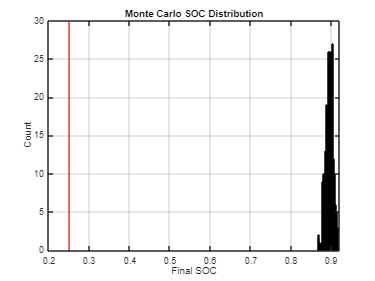


% PLOT 6: Monte Carlo Histogram (Route A)
figure;
histogram(SOC_mc(:,1),25);
xline(SOC_reserve,'r','LineWidth',2);
xlabel('Final SOC'); ylabel('Count');
title('Monte Carlo SOC Distribution');
grid on;

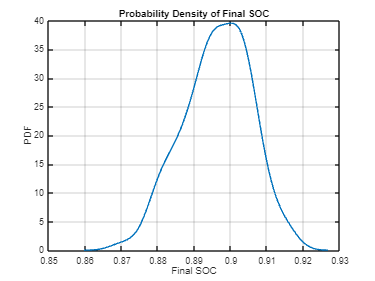


% PLOT 7: SOC PDF (Risk Insight)
figure;
ksdensity(SOC_mc(:,1));
xlabel('Final SOC'); ylabel('PDF');
title('Probability Density of Final SOC');
grid on;

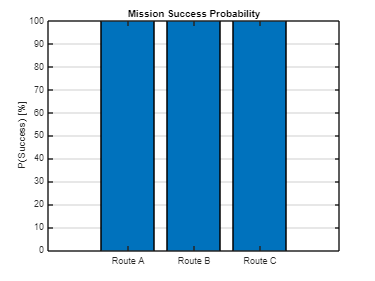


% PLOT 8: Success Probability
figure;
bar([results.P_success]*100);
set(gca,'XTickLabel',{results.name});
ylabel('P(Success) [%]');
title('Mission Success Probability');
grid on;

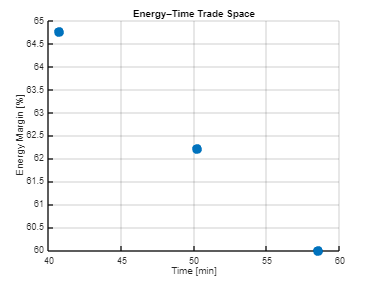


% PLOT 9: Energy vs Time Trade
figure;
scatter([results.time_total]/60, [results.energy_margin]*100,120,'filled');
xlabel('Time [min]');
ylabel('Energy Margin [%]');
title('Energy–Time Trade Space');
grid on;

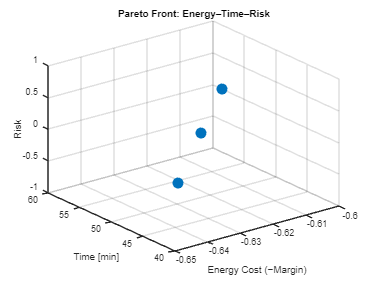


% PLOT 10: Pareto Front (Energy–Time–Risk)
figure;
scatter3(-[results.energy_margin], [results.time_total]/60, ...
         [results.risk], 150,'filled');
xlabel('Energy Cost (−Margin)');
ylabel('Time [min]');
zlabel('Risk');
title('Pareto Front: Energy–Time–Risk');
grid on;


%% ========================================================================
% 13. SUMMARY
% ========================================================================

disp('================ MISSION SUMMARY ================');

================ MISSION SUMMARY ================


for r = 1:length(results)
    fprintf('%s\n',results(r).name);
    fprintf(' Final SOC      : %.2f %%\n',results(r).SOC_final*100);
    fprintf(' Energy Margin  : %.2f %%\n',results(r).energy_margin*100);
    fprintf(' Time           : %.1f min\n',results(r).time_total/60);
    fprintf(' P(success)     : %.2f %%\n',results(r).P_success*100);
    fprintf(' RTB OK         : %d\n',results(r).RTB_ok);
    fprintf(' ToT OK         : %d\n\n',results(r).ToT_ok);
end

Route A


 Final SOC      : 89.76 %


 Energy Margin  : 64.76 %


 Time           : 40.7 min


 P(success)     : 100.00 %


 RTB OK         : 1


 ToT OK         : 0



Route B


 Final SOC      : 87.22 %


 Energy Margin  : 62.22 %


 Time           : 50.2 min


 P(success)     : 100.00 %


 RTB OK         : 1


 ToT OK         : 0



Route C


 Final SOC      : 85.00 %


 Energy Margin  : 60.00 %


 Time           : 58.6 min


 P(success)     : 100.00 %


 RTB OK         : 1


 ToT OK         : 0



disp('===============================================');


%% ========================================================================
% 14. LOCAL FUNCTION
% ========================================================================

function [s, SOC, time, power] = mission_model(dist, V_air, V_loiter, ...
    loiter_time, P_cruise, rho, S, CD0, k, W, ds, Vw, ...
    E_batt_max, SOC_init)

s = 0:ds:dist;
SOC = zeros(size(s));
time = zeros(size(s));
power = zeros(size(s));

SOC(1) = SOC_init;

for i = 2:length(s)
    Vg = max(V_air + Vw,2);
    dt = ds / Vg;
    SOC(i) = SOC(i-1) - (P_cruise*dt)/E_batt_max;
    time(i) = time(i-1) + dt;
    power(i) = P_cruise;
end

if loiter_time > 0
    CL = W / (0.5 * rho * V_loiter^2 * S);
    CD = CD0 + k * CL^2;
    D  = 0.5 * rho * V_loiter^2 * S * CD;
    P_loiter = D * V_loiter;
    SOC(end) = SOC(end) - (P_loiter*loiter_time)/E_batt_max;
    time(end) = time(end) + loiter_time;
end

end
